# 1. Beam-state initialization test - MATLAB

Run beam_state_test.ipynb first, then Run All in this file or its .mlx. Both MATLAB files contain the same test; do not run the full solver. Raw inputs only: no Python results, harmonics or calculated grid are loaded. Lengths: mm. Frequencies: GHz. Voltage: kV. Current: A. Phases: radians. case_name selects a prescribed fixture in the Python input cell. Y0 is already one-based in inputs.mat; do not add 1 again.

test_directory = fileparts(mfilename('fullpath'));
if ~isfile(fullfile(test_directory, 'beam_state_test.m'))
    test_file = matlab.desktop.editor.getActiveFilename;
    test_directory = fileparts(test_file);
    if ~isfile(fullfile(test_directory, 'beam_state_test.m'))
        test_directory = fileparts(which('beam_state_test.m'));
    end
end
input_file = fullfile(test_directory, 'inputs.mat');
assert(isfile(input_file), ...
    'Cannot find inputs.mat at: %s\nRun beam_state_test.ipynb first.', input_file);
load(input_file);
assert(rc ~= 0 && yd == 0, 'This test uses the cylindrical-beam grid.');
assert(Nt >= 16 && Ns >= 1 && Ns < Nt/2, 'Use 1 <= Ns < Nt/2 and Nt >= 16.');

## 2. Reference beam and grid - Original KLJCmainsv22.m lines 45-86

Copied exactly, including the original constants and type conversions. The intervening source-window and cavity-field blocks are not needed here.

CALCULATE THE REFERENCE PAMAMETER

Nt = double(Nt)

Nt = 128


Iz0=1/2/pi*2*pi/Nt*sum(Izt(Y0)); % A, araverge emission current
I0=abs(Iz0);
U0=1/2/pi*2*pi/Nt*sum(Izt(Y0).*Ut(Y0))/Iz0;% kV, average emission voltage

% constant
c=299792458;  % m/s, light speed
etom=-1.7588E11;  % C/kg, charge to mass of electron
eta0=4E-7*pi*c; % ohm, wave impendance of TEM

esign=sign(-etom); % for negative charged paticles, esign=1; for postive charged particles, esign=-1
etom=abs(etom);

etom = double(etom);
c    = double(c);
U0   = double(U0);

s=(1-(1+etom/c/c*U0*1E3)^(-2))^(1/2); % ve0/c
vetoc=(1-(1+etom/c/c*Ut*1E3).^(-2)).^(1/2); % vet/c
vn1=0*vetoc;
vn1(Y0)=s./vetoc(Y0); % ve0/ve(t) at the entrance


w=2*pi*f*1E9;  % rad/s, angular frequency of operating
w0=2*pi*f0*1E9;  % rad/s, angular frequency of resonant
k0=w0/c/1000;   % 1/mm,  wave number at resonant freqency
Lsb=pi*ones(1,Nc); % phaseshift beta0*Ls from the entrance of output cavity at resonant freqency

gama=1+etom*U0*1000/c/c; % Lorentz factor
betae=w/c/s/1000;  % 1/mm, betae at operating freqency

Nz = double(Nz);
dz=2*pi/betae/Nz;  % mm,

dz=L/floor(L/dz); % mm, increment of z
dz = double(dz);
zi=(z0:dz:z0+L)'; % mm, z position sequence

rcvs=interp1(rcv(1,:),rcv(2,:)*rc,zi,'linear','extrap'); % mm, tunnel radius sequence

## 3. Normalized coordinates - Original lines 132-133

z=betae*zi; % normalized z position
dt=betae*dz; % normalized time step & normalized position step, in real time step=position step/injecting velocity of electron

## 4. Initialize current and charge harmonics - Original lines 136-149

Columns k=1..Ns are harmonics, not cavity indices. All active Y0 samples contribute; Nt still counts the full RF period.

Iz=zeros(length(z),Ns);
QQ=zeros(length(z),Ns);

% intial value given
Y=Y0;
IzDC=1/2/pi*(2*pi/Nt)*sum(Izt(Y)/Iz0)*ones(length(z),1); % normalized DC current along the axis
for k=1:Ns
    Iz(:,k)=1i/pi*(2*pi/Nt)*sum(Izt(Y)/Iz0.*exp(-k*1i*tn1(Y)))*ones(length(z),1); % normalized,intial modulated current of 1st harmonic
end

QQDC=1/2/pi*(2*pi/Nt)*sum(Izt(Y)/Iz0.*vn1(Y))*ones(length(z),1); % DC charge density along axis
for k=1:Ns
    QQ(:,k)=1i/pi*(2*pi/Nt)*sum(Izt(Y)/Iz0.*exp(-k*1i*tn1(Y)).*vn1(Y))*ones(length(z),1); % normalized,intial modulated charged density
end

## 5. Initial mean beam quantities - Original lines 157-159

The plasma-frequency calculation at lines 151-155 is intentionally omitted. It belongs to space charge, not BeamState.initialize.

effe=0*ones(length(z),1); % if all electron reflected, the efficiency will be 100%
vez=1*ones(length(z),1); % ve/ve0
gamaz=(1-(vez*s).^2).^(-1/2);

## 6. Inspect the initialized quantities

Everything below is test-only plotting, checking and export.

fprintf('Case: %s; Nt=%d; active=%d; Ns=%d; nodes=%d\n', ...
    case_name, Nt, length(Y0), Ns, length(z));

Case: uniform; Nt=128; active=128; Ns=8; nodes=3806


Variable={'Iz0';'I0';'U0';'s';'gama';'IzDC(1)';'QQDC(1)';'effe(1)';'vez(1)';'gamaz(1)'};
Value=[Iz0;I0;U0;s;gama;IzDC(1);QQDC(1);effe(1);vez(1);gamaz(1)];
Unit={'A';'A';'kV';'1';'1';'1';'1';'1';'1';'1'};
disp(table(Variable,Value,Unit));

      Variable       Value      Unit 
    ____________    _______    ______

    {'Iz0'     }        -16    {'A' }
    {'I0'      }         16    {'A' }
    {'U0'      }        180    {'kV'}
    {'s'       }    0.67315    {'1' }
    {'gama'    }     1.3522    {'1' }
    {'IzDC(1)' }          1    {'1' }
    {'QQDC(1)' }          1    {'1' }
    {'effe(1)' }          0    {'1' }
    {'vez(1)'  }          1    {'1' }
    {'gamaz(1)'}     1.3522    {'1' }




style_axes = @(fig) set(findall(fig,'Type','axes'), ...
    'XGrid','on','YGrid','on','GridLineStyle','--', ...
    'GridColor',[0.5 0.5 0.5],'GridAlpha',0.45);

## 7. Prescribed departure and entrance samples

Gray lines include inactive samples. Markers identify the samples used. vn1 = v_reference/v_sample on Y0; it is zero for inactive samples.

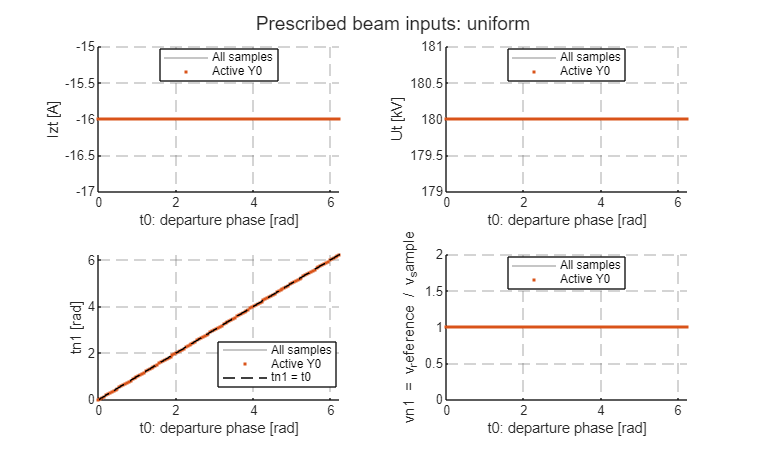

figure('Name','Beam inputs','Position',[100 100 1100 650]);
tiledlayout(2,2);
sample_values={Izt,Ut,tn1,vn1};
sample_labels={'Izt [A]','Ut [kV]','tn1 [rad]','vn1 = v_reference / v_sample'};
for panel=1:4
    nexttile; hold on;
    values=sample_values{panel};
    plot(t0,values,'Color',[0.7 0.7 0.7],'DisplayName','All samples');
    plot(t0(Y0),values(Y0),'.','DisplayName','Active Y0');
    if panel==3
        plot(t0,t0,'k--','DisplayName','tn1 = t0');
    end
    xlabel('t0: departure phase [rad]'); ylabel(sample_labels{panel});
    legend('Location','best');
end
sgtitle(['Prescribed beam inputs: ',case_name],'Interpreter','none');
style_axes(gcf);

## 8. Harmonics including harmonic zero

Display-only matrices: Iz and QQ themselves still have Ns columns. The extra i in the original definition is part of the complex convention. All coefficients are dimensionless. QQ also weights by vn1.

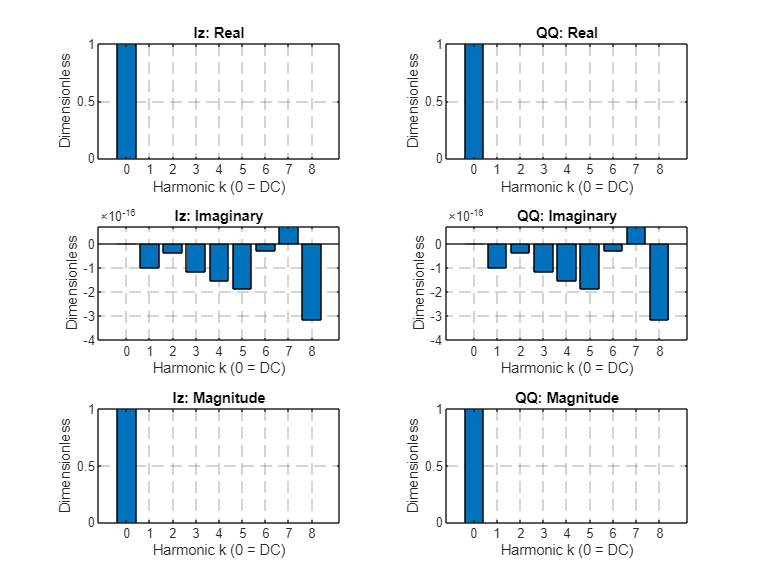

harmonics=0:Ns;
Iz_plot=[IzDC,Iz];
QQ_plot=[QQDC,QQ];
figure('Name','Current and charge harmonics','Position',[100 80 1100 850]);
tiledlayout(3,2);
parts={@real,@imag,@abs};
part_labels={'Real','Imaginary','Magnitude'};
for row=1:3
    for column=1:2
        nexttile;
        if column==1
            values=Iz_plot(1,:); name='Iz';
        else
            values=QQ_plot(1,:); name='QQ';
        end
        bar(harmonics,parts{row}(values));
        xticks(harmonics); xlabel('Harmonic k (0 = DC)'); ylabel('Dimensionless');
        title([name,': ',part_labels{row}]);
    end
end
style_axes(gcf);

% .' is non-conjugating: preserve the complex signs in the displayed table.
disp(table(harmonics.',Iz_plot(1,:).',QQ_plot(1,:).', ...
    'VariableNames',{'Harmonic','Iz','QQ'}));

    Harmonic              Iz                         QQ           
    ________    _______________________    _______________________

       0                  1+0i                       1+0i         
       1        -1.4095e-18-9.8879e-17i    -1.4095e-18-9.8879e-17i
       2          2.884e-17-3.8164e-17i      2.884e-17-3.8164e-17i
       3        -4.8572e-17-1.1449e-16i    -4.8572e-17-1.1449e-16i
       4         3.1225e-17-1.5266e-16i     3.1225e-17-1.5266e-16i
       5         8.2399e-17-1.8735e-16i     8.2399e-17-1.8735e-16i
       6        -6.8522e-17-3.0358e-17i    -6.8522e-17-3.0358e-17i
       7         2.0817e-17+7.1991e-17i     2.0817e-17+7.1991e-17i
       8          1.223e-16-3.1676e-16i      1.223e-16-3.1676e-16i



## 9. Initial profiles along the grid

These flat arrays are initial guesses, not a beam propagated through RF fields. effe=0, vez=1, gamaz=gama even when prescribed sample voltages differ.

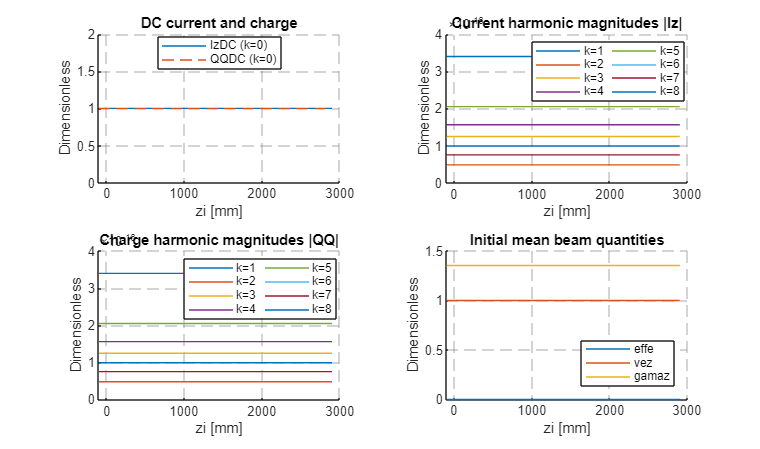

figure('Name','Initialized beam profiles','Position',[100 100 1100 650]);
tiledlayout(2,2);
nexttile; hold on;
plot(zi,IzDC,'DisplayName','IzDC (k=0)');
plot(zi,QQDC,'--','DisplayName','QQDC (k=0)');
xlabel('zi [mm]'); ylabel('Dimensionless'); title('DC current and charge');
legend('Location','best');
nexttile; hold on;
for k=1:Ns
    plot(zi,abs(Iz(:,k)),'DisplayName',sprintf('k=%d',k));
end
xlabel('zi [mm]'); ylabel('Dimensionless'); title('Current harmonic magnitudes |Iz|');
legend('Location','best','NumColumns',2);
nexttile; hold on;
for k=1:Ns
    plot(zi,abs(QQ(:,k)),'DisplayName',sprintf('k=%d',k));
end
xlabel('zi [mm]'); ylabel('Dimensionless'); title('Charge harmonic magnitudes |QQ|');
legend('Location','best','NumColumns',2);
nexttile; hold on;
plot(zi,effe,'DisplayName','effe');
plot(zi,vez,'DisplayName','vez');
plot(zi,gamaz,'DisplayName','gamaz');
xlabel('zi [mm]'); ylabel('Dimensionless'); title('Initial mean beam quantities');
legend('Location','best');
style_axes(gcf);

## 10. Entrance waveform reconstruction

Current(theta) = IzDC + imag(sum_k Iz_k*exp(i*k*theta)). The same convention applies to QQ. Inactive samples have zero weights. Finite Ns causes truncation ringing for a partially active beam. This is a Fourier visualization, not a beam-dynamics computation.

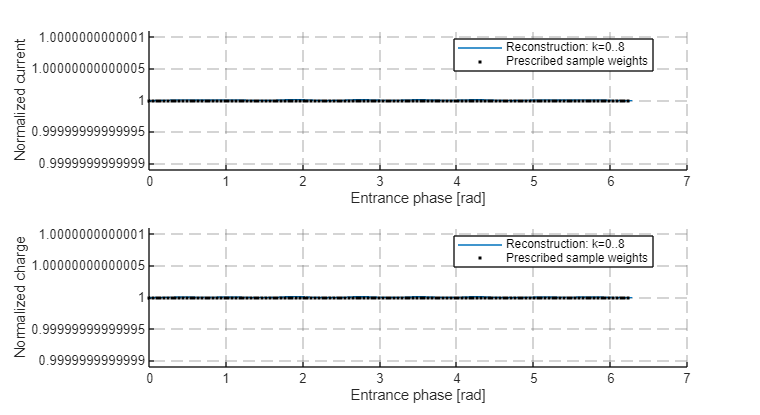

theta=linspace(min(tn1),min(tn1)+2*pi,600).';
phase=exp(1i*theta*(1:Ns));
current_samples=zeros(1,Nt);
current_samples(Y0)=Izt(Y0)/Iz0;
charge_samples=current_samples.*vn1;
figure('Name','Entrance waveform reconstruction','Position',[100 100 1100 600]);
tiledlayout(2,1);
nexttile; hold on;
plot(theta,IzDC(1)+imag(phase*Iz(1,:).'),'DisplayName',sprintf('Reconstruction: k=0..%d',Ns));
plot(tn1,current_samples,'k.','DisplayName','Prescribed sample weights');
xlabel('Entrance phase [rad]'); ylabel('Normalized current'); legend('Location','best');
nexttile; hold on;
plot(theta,QQDC(1)+imag(phase*QQ(1,:).'),'DisplayName',sprintf('Reconstruction: k=0..%d',Ns));
plot(tn1,charge_samples,'k.','DisplayName','Prescribed sample weights');
xlabel('Entrance phase [rad]'); ylabel('Normalized charge'); legend('Location','best');
style_axes(gcf);

## 11. Basic MATLAB consistency checks

No Python output is used in these tests.

assert(isequal(size(Iz),[length(z),Ns]) && isequal(size(QQ),[length(z),Ns]));
assert(isequal(size(IzDC),[length(z),1]) && isequal(size(QQDC),[length(z),1]));
assert(isequal(size(effe),[length(z),1]) && isequal(size(vez),[length(z),1]));
assert(isequal(size(gamaz),[length(z),1]));
assert(all(isfinite([Iz,QQ,IzDC,QQDC,effe,vez,gamaz]),'all'));
assert(all(abs(Iz-Iz(1,:)) <= 1e-12+1e-10*abs(Iz(1,:)),'all'));
assert(all(abs(QQ-QQ(1,:)) <= 1e-12+1e-10*abs(QQ(1,:)),'all'));
assert(all(abs(IzDC-1) <= 1e-12+1e-10));
assert(all(abs(QQDC-mean(charge_samples)) <= 1e-12+1e-10*abs(mean(charge_samples))));
assert(all(effe==0) && all(vez==1));
assert(all(abs(gamaz-gama) <= 1e-12+1e-10*abs(gama)));

% Independent FFT check for equally spaced entrance phases.
if all(abs(tn1-(tn1(1)+2*pi*(0:Nt-1)/Nt)) <= 1e-12)
    phase_shift=exp(-1i*(1:Ns)*tn1(1));
    current_fft=fft(current_samples);
    charge_fft=fft(charge_samples);
    expected_Iz=2i/Nt*current_fft(2:Ns+1).*phase_shift;
    expected_QQ=2i/Nt*charge_fft(2:Ns+1).*phase_shift;
    assert(all(abs(Iz(1,:)-expected_Iz) <= 1e-12+1e-10*abs(expected_Iz)));
    assert(all(abs(QQ(1,:)-expected_QQ) <= 1e-12+1e-10*abs(expected_QQ)));
end
if all(abs(vn1(Y0)-1) <= 1e-12)
    assert(all(abs(QQ-Iz) <= 1e-12+1e-10*abs(Iz),'all'));
    assert(all(abs(QQDC-IzDC) <= 1e-12+1e-10*abs(IzDC)));
end
disp('PASS: MATLAB beam-state initialization checks.');

PASS: MATLAB beam-state initialization checks.


disp('The Python-MATLAB comparison is a separate step.');

The Python-MATLAB comparison is a separate step.


## 12. Export MATLAB results

Same seven state arrays and twelve reference/grid quantities as Python. Nt/Ns and case_name are test metadata. Complex coefficients are preserved. Ordinary MAT format; only this test's matlab_results.mat is overwritten.

save(fullfile(test_directory,'matlab_results.mat'), ...
    'Iz0','I0','U0','s','vetoc','vn1','gama', ...
    'betae','dz','zi','z','dt', ...
    'Iz','QQ','IzDC','QQDC','effe','vez','gamaz','Nt','Ns','case_name','-v7');
fprintf('Saved: %s\n',fullfile(test_directory,'matlab_results.mat'));

Saved: C:\Users\lsito\Desktop\PyKlyC\pyKlyC\test\3.beam_state_test\matlab_results.mat


disp('Next: run compare_results.ipynb.');

Next: run compare_results.ipynb.
